# Graphene Euler-Bernoulli beam (dynamic, 1d)

## Global constants

cantilever = false;

% from Lee, D. Wei's paper
L = 1; % length of the beam
rho = 1; % density of the material
E = 1; % young's modulus
sigma_max = .13;
D = -15*(E^2)/(4*sigma_max); % nonlinear elastic modulus
I1 = 1; % moment of inertia
I2 = 0.02; % moment of inertia
% F = 10e6; % external force
if cantilever
    F = -1;
else
    F = -4;
end

A = 1; % cross-section area (b*h)
B = E*I1;
C = D*I2;
C3 = 1/(12*C^2*F)*(6*B*C*F*L - B^3 + (B^2-4*C*F*L)^(3/2));
C4 = 1/(12*C^2*F)*(B^3*L -3*B*C*F*L^2 + 1/(10*C*F)*((B^2-4*C*F*L)^(5/2) - B^5)) + L*C3;

## FEM config

Nb = 4; % number of dof per element
gauss_points_num = 8;
master = [0 1];
Npts = 100; % for plotting

% linear elements
coeffs =   [1,0,-3,2; 
            0,1,-2,1;
            0,0,3,-2;
            0,0,-1,1];

## Matrix assembly

NEL = 10;
h = L/NEL;

% basis functions on the master element
N = basis_functions(coeffs);
d2_N = basis_derivatives(coeffs, 2);
d3_N = basis_derivatives(coeffs, 3);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

% element nodes
es = zeros(NEL,2);
for i=1:NEL
    es(i,:) = [xs(i) xs(i+1)];
end

% local stiffness and mass matrices
Kl = zeros(Nb,Nb,NEL);
Ml = zeros(Nb,Nb,NEL);
fl = zeros(Nb,1,NEL);
for k=1:NEL
    for i=1:Nb
        for j=1:Nb
            Kl(i,j,k) = 1 / (hs(k))^3 * gauss(@(x) d2_N(i,x) * d2_N(j,x), master(1), master(2), gauss_points_num);
            Ml(i,j,k) =      hs(k)    * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
        end
        fl(i,1,k)     = F *  hs(k)    * gauss(@(x) N(i,x), master(1), master(2), gauss_points_num);
    end
end

% Global matrices and force term
Kn = (NEL+1)*2;
K = zeros(Kn,Kn); M = zeros(Kn,Kn);
f = zeros(Kn,1);

for i=1:NEL
    K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Kl(1:Nb,1:Nb,i);
    M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Ml(1:Nb,1:Nb,i);
    f(2*i-1:2*i+Nb-2,1) = f(2*i-1:2*i+Nb-2,1) + fl(1:Nb,1,i);
end

% K = K(3:end, 3:end);
K1 = E*I1*K;
K2 = D*I2*K;
if cantilever == true
    K2 = K2(3:end,3:end);
else
    K2 = K2(3:end-2,3:end-2);
end

% size(K)
% condest(K)
% M = M(3:end, 3:end);
M = rho*M;
% size(M)
% condest(M)
% f = f(3:end);

## Solver prep

% IC
% v = @(x) 1/(12*C^2*F)*(B^2*x-6*B*C*F*L*x+3*B*C*F*x^2-B^3*L+3*B*C*F*L^2) - 1/(120*C^3*F^2) * ((B^2-4*C*F*L+4*C*F*x)^(5/2)-B^5) + C3*(x-L) + C4;
% dv = @(x) 1/(12*C^2*F)*(B^2-6*B*C*F*L+6*B*C*F*x) - 1/(120*C^3*F^2) * (5/2)*(B^2-4*C*F*L+4*C*F*x)^(3/2)*4*C*F + C3;

% v = @(x) 1e-6.*x.^2;
% dv = @(x) 2e-6.*x;
% w = @(x) 0;
% dw = @(x) 0;

v = @(x) 0;
dv = @(x) 0;
w = @(x) 0;
dw = @(x) 0;

% plot((0:h:L), arrayfun(w,(0:h:L)))

vs = project(v, dv, xs);
ws = project(w, dw, xs);

T0 = 0; 
if cantilever
    Tf = 2.5e1;
    tau = 1e-1; 
else
    Tf = 5e0;
    tau = 2e-2;
end

Ntsteps = round(Tf/tau+1);

lambda = tau^2;

Amat = M+lambda/4*K1;
Bmat = 2*M-lambda/2*K1;

if cantilever == true
    K1 = K1(3:end,3:end);
    M = M(3:end, 3:end);
    
    f = lambda*f;
    
    Amat = sparse(Amat(3:end, 3:end));
    Bmat = sparse(Bmat(3:end, 3:end));
    f = f(3:end, 1);
else
    K1 = K1(3:end-2,3:end-2);
    M = M(3:end-2, 3:end-2);
    
    f = lambda*f;
    
    Amat = sparse(Amat(3:end-2, 3:end-2));
    Bmat = sparse(Bmat(3:end-2, 3:end-2));
    f = f(3:end-2, 1);
end

% Use fixed point iteration for u
% Start with the initial guess
us = zeros(Kn,Ntsteps);
us(:,1) = vs;

% implicit scheme
options = optimset('Display','off');

if cantilever 
    func1 = @(soln) 2*Amat*soln - (Bmat*us(3:end,1) + 2*tau*Amat*ws(3:end) + f - lambda*K2*hfun((soln + us(3:end,1) - tau*ws(3:end,1))/2));
    us(3:end,2) = fsolve(func1, ones(length(K)-2,1),options);
    
    for j=3:Ntsteps
        func2 = @(soln) Amat*soln - (Bmat*us(3:end,j-1) - Amat*us(3:end,j-2) + f - lambda*K2*hfun((soln + 2*us(3:end,j-1) + us(3:end,j-2))/4));
        us(3:end,j) = fsolve(func2,ones(length(K)-2,1),options);
    end
else
    func1 = @(soln) 2*Amat*soln - (Bmat*us(3:end-2,1) + 2*tau*Amat*ws(3:end-2) + f - lambda*K2*hfun((soln + us(3:end-2,1) - tau*ws(3:end-2,1))/2));
    us(3:end-2,2) = fsolve(func1, ones(length(K)-4,1),options);
    
    for j=3:Ntsteps
        func2 = @(soln) Amat*soln - (Bmat*us(3:end-2,j-1) - Amat*us(3:end-2,j-2) + f - lambda*K2*hfun((soln + 2*us(3:end-2,j-1) + us(3:end-2,j-2))/4));
        us(3:end-2,j) = fsolve(func2,ones(length(K)-4,1),options);
    end
end

us2 = zeros(Kn,Ntsteps);
us2(:,1) = vs;

if cantilever
    us2(3:end,2) = (2*Amat)\(Bmat*us2(3:end,1) + 2*tau*Amat*ws(3:end) + f);
    
    for j=3:Ntsteps
        us2(3:end,j) = Amat\(Bmat*us2(3:end,j-1) - Amat*us2(3:end,j-2) + f); 
    end
else
    us2(3:end-2,2) = (2*Amat)\(Bmat*us2(3:end-2,1) + 2*tau*Amat*ws(3:end-2) + f);
    
    for j=3:Ntsteps
        us2(3:end-2,j) = Amat\(Bmat*us2(3:end-2,j-1) - Amat*us2(3:end-2,j-2) + f); 
    end
end

xxxs = linspace(0,L,Npts);
u_full = zeros(length(xxxs),Ntsteps);
u_full2 = zeros(length(xxxs),Ntsteps);

for j=1:Ntsteps
    % local u coefficients
    u_locals = zeros(NEL, Nb);
    for i=1:NEL
        u_locals(i,1:end) = us(2*i-1: 2*i+Nb-2,j);
    end
    
    u_locals2 = zeros(NEL, Nb);
    for i=1:NEL
        u_locals2(i,1:end) = us2(2*i-1: 2*i+Nb-2,j);
    end
    
    % producing piecewise polynomial approximation
    
    u_vals = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals(i) = u_fun(u_locals, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full(1:end,j) = u_vals;
    
    u_vals2 = zeros(length(xxxs),1);
    for i=1:length(xxxs)
        u_vals2(i) = u_fun(u_locals2, xxxs(i), NEL, Nb, N, es, xs);
    end
    u_full2(1:end,j) = u_vals2;
end

## Plotting

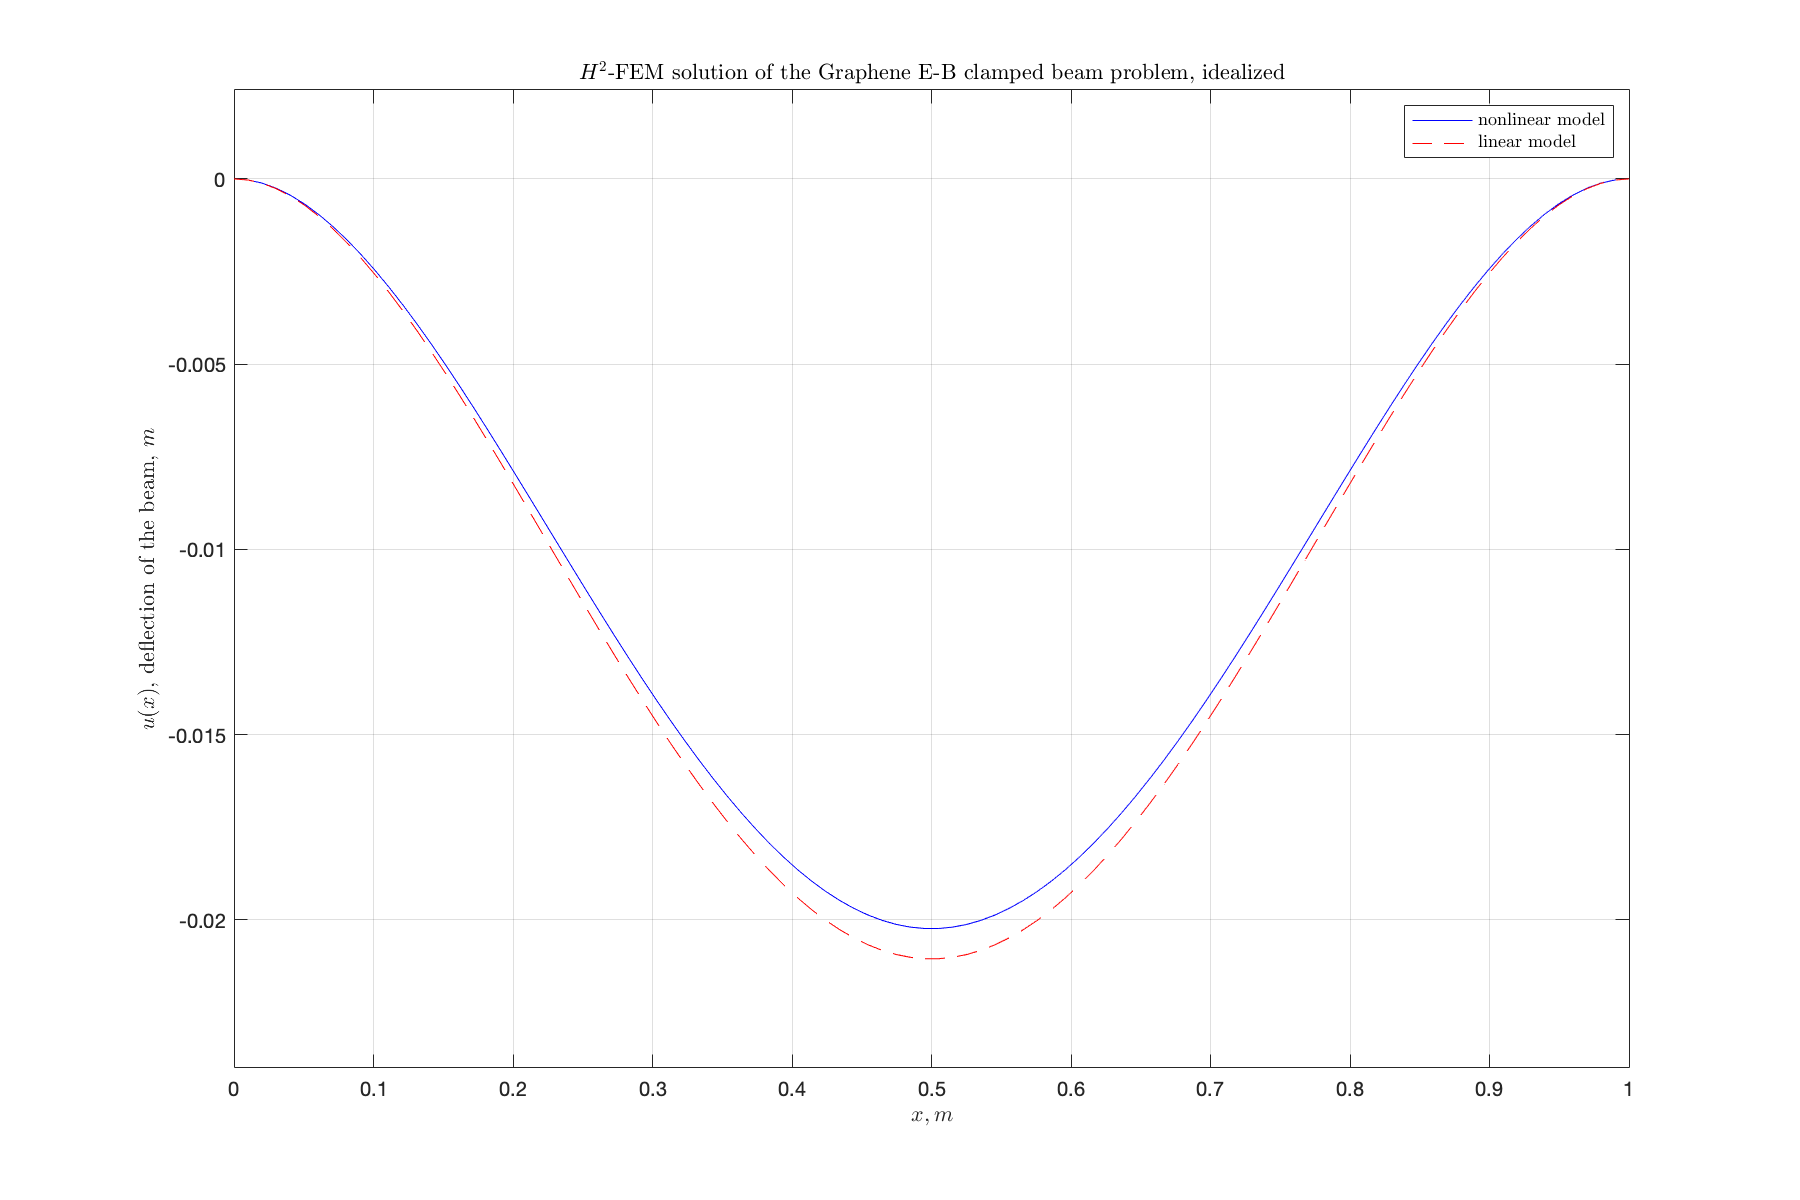

figure('Position', [10 10 900 600])
for j=1:Ntsteps
    plot(xxxs,u_full(1:end,j),'b-', xxxs,u_full2(1:end,j),'r--') 
    grid on
    xlim([0 L])
    if cantilever
        ylim([-0.3,0.03])
        title("$H^2$-FEM solution of the Graphene E-B cantilever beam problem, idelized", "Interpreter","latex")
    else 
        ylim([-0.024,0.0024])
        title("$H^2$-FEM solution of the Graphene E-B clamped beam problem, idealized", "Interpreter","latex")
    end
    xlabel('$x, m$', "Interpreter","latex")
    ylabel('$u(x)$, deflection of the beam, $m$', "Interpreter","latex")
    
    leg = legend('nonlinear model','linear model');    
    set(leg,'Interpreter','latex');    
    
    hold off
    pause(.05)
end

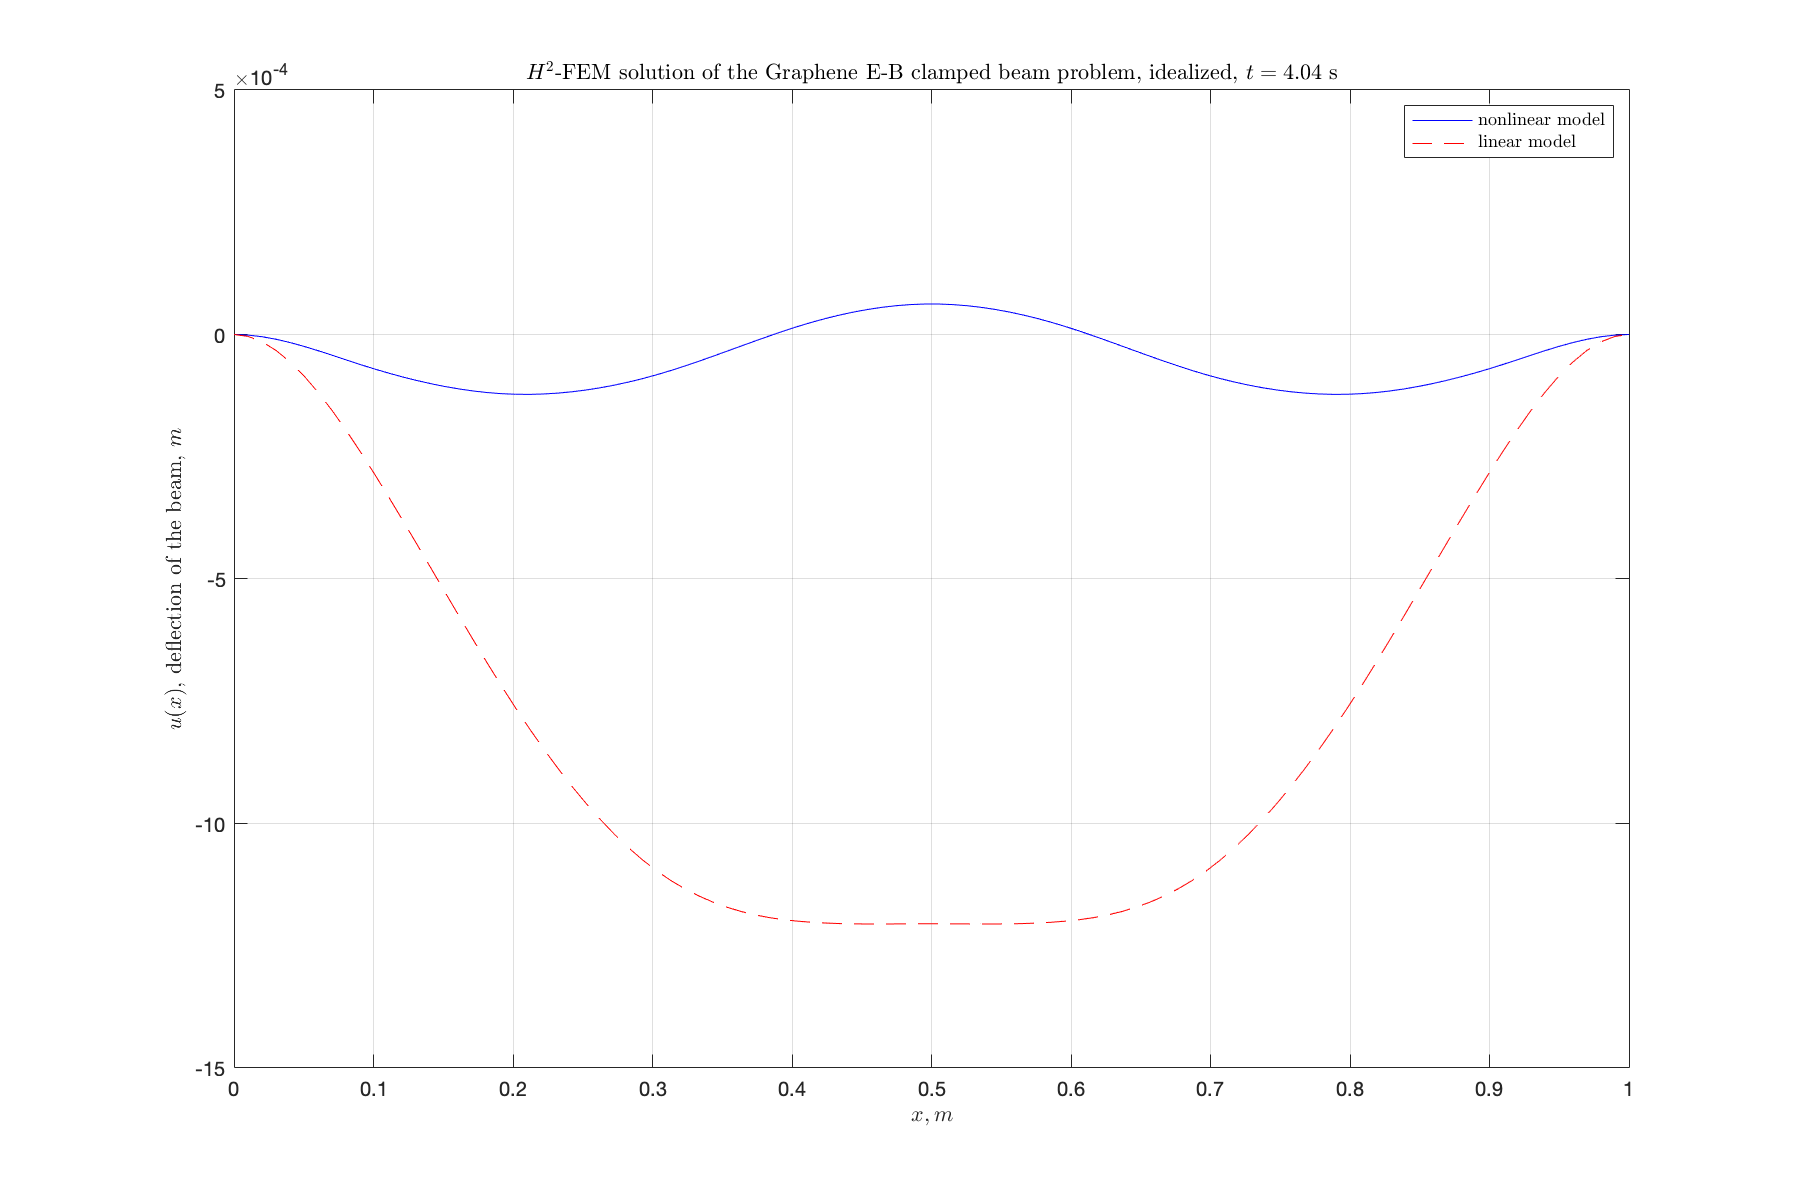

if ~cantilever
    j=202;
    figure('Position', [10 10 900 600])
    plot(xxxs,u_full(1:end,j),'b-', xxxs,u_full2(1:end,j),'r--') 
    grid on
    xlim([0 L])
    if cantilever
        ylim([-0.3,0.03])
        title("$H^2$-FEM solution of the Graphene E-B cantilever beam problem, idealized", "Interpreter","latex")
    else 
        ylim([-1.5*1e-3,0.5*1e-3])
        title(sprintf("$H^2$-FEM solution of the Graphene E-B clamped beam problem, idealized, $t=%3.2f$ s",tau*j), "Interpreter","latex")
    end
    xlabel('$x, m$', "Interpreter","latex")
    ylabel('$u(x)$, deflection of the beam, $m$', "Interpreter","latex")
    
    leg = legend('nonlinear model','linear model');    
    set(leg,'Interpreter','latex');    
    
    hold off
end

## FEM tools

function res = chi(e,x,xs) 
    res = false;
    if x > xs(e) && x <= xs(e+1)
        res = true;
    end
end

function res = xi(x,xe)
     res = (x - xe(1)) / (xe(2) - xe(1));
end

% assemble u(x) from u_i coefficients
function res = u_fun(u_locals, x, NEL, Nb, N, es, xs)
    res = 0;
    for i=1:NEL
        sm = 0;
        for j=1:Nb
            sm = sm + u_locals(i,j) * N(j,xi(x,es(i,:)));
        end
        sm = sm * chi(i,x,xs);
        res = res + sm;
    end
end

## Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end

## Projection onto FE space

function proj = project(fun, dfun, xs)
    proj = zeros(2*length(xs),1);
    for i=1:length(xs)
        proj(2*i-1) =  fun(xs(i));
        proj(2*i)   = dfun(xs(i));
    end
end

function res = hfunc(x)
    res = abs(x)*x;
end

function res = d_hfunc(x)
    res = 2*abs(x);
end

% p-laplacian
function res = hfun(x)
    n = length(x);
    res = zeros(n,1);
    for i=1:n
        if rem(i, 2) == 1
            res(i) = hfunc(x(i));
        else
            res(i) = d_hfunc(x(i-1))*x(i);
        end
    end
end